# Data preparation

clc
clearvars
close all

exp_num = "exp51";
group = "wt";
calib_dir = strcat("calib_",exp_num);

meta_info = readtable(strcat("meta_info_",group,".csv"));
% meta_info_ko = readtable("meta_info_ko.csv");
fnames = meta_info.trace_file_name_4half;
meta_info = meta_info(~cellfun(@(x)isequal(x,'NA'), fnames), :);

current_names = {'iktof','ikslow1','ikslow2','ikss'};
tune_idx = cell(5,1);
tune_idx{1} = [1, 2, 4, 5, 7, 11, 13];
tune_idx{2} = [2, 3];
tune_idx{3} = [1, 2, 4, 5, 9, 10 11];
tune_idx{4} = [2, 3];
tune_idx{5} = [1, 2, 3, 4];
[mdl_struct,psize] = gen_mdl_struct(current_names,tune_idx);

weeks = unique(meta_info.weeks);
sol_container = cell(length(weeks),1);

for i=1:length(weeks)
    sub_meta = meta_info(meta_info.weeks == weeks(i),:);
    sol_mx = NaN(size(sub_meta,1),psize);
    for j=1:size(sub_meta,1)
        fname = sub_meta(j,:).trace_file_name_4half;
        fpath = fullfile(calib_dir,group,fname);
        sol = table2array(readtable(fpath));
        sol_mx(j,:) = gen_sol_vec(sol,mdl_struct,psize);
    end
    sol_container{i} = sol_mx;
end

# Simple univariate plots

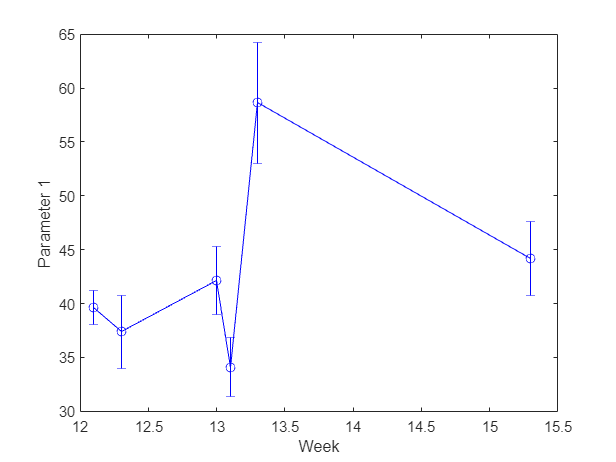

idx_group1 = [1,2,3,]
idx_group2 = [];
idx_group3 = [];
idx_group4 = [];

pidx = 1;
pmean = NaN(length(weeks),1);
pvar = NaN(length(weeks),1);

for i=1:length(weeks)
    pmean(i) = mean(sol_container{i}(:,pidx));
    pvar(i) = std(sol_container{i}(:,pidx))/sqrt(size(sol_container{i},1));
end

errorbar(weeks,pmean,pvar,'-o','Color','blue')
xlabel("Week")
ylabel(strcat("Parameter ",num2str(pidx)))

function [mdl_struct, psize] = gen_mdl_struct(current_names,tune_idx)
    num_currents = length(current_names);
    
    % index 1
    idx_info1 = cell(1,num_currents);
    for i = 1:num_currents
        switch current_names{i}
            case 'iktof'
                idx_info1{i} = tune_idx{1};
            case 'iktos'
                idx_info1{i} = tune_idx{2};
            case 'ikslow1'
                idx_info1{i} = tune_idx{3};
            case 'ikslow2'
                idx_info1{i} = tune_idx{4};
            case 'ikss'
                idx_info1{i} = tune_idx{5};
        end
    end

    % index 2
    idx_info2 = cell(1,num_currents);
    psize = 0;
    for i = 1: num_currents
        psize_old = psize;
        psize = psize + length(idx_info1{i});
        idx_info2{i} = (1+psize_old):(psize);
    end

    model_info = [current_names; idx_info1; idx_info2];
    field_names = ["name","idx1","idx2"];
    mdl_struct = cell2struct(model_info, field_names, 1);    
end

function sol = gen_sol_vec(sol_mx, model_struct, psize)
    sol = zeros(1, psize);
    for i = 1:length(model_struct)
        running_sol = sol_mx(:, i);
        running_sol = running_sol(~isnan(running_sol));
        sol(model_struct(i).idx2) = running_sol(model_struct(i).idx1);
    end
end